# LABORATORIO 3 - CON CIDFICADOR DE BLOQUE

## Parámetros de entrada


%parametros de modulador
NumeroBTx=1002*5000%Número de bits

NumeroBTx = 5010000

M=4             %4-PSK             

M = 4

n=log2(M)       %Cada símbolo contiene 2 bits

n = 2

N=0

N = 0

%parametros de codificador de bloque (hamming extendido 6,3)
nc=6;           %Numero de bits de un bloque de código
k=3;            %Número de bits de mensaje
t=1;            %Corrección de un bit de error por bloque de codigo
%Parámetros de snr
expn=0.5:0.1:1.5;
snr=10.^expn;
snrdB=10.*expn; %[2-15]dB
yb=snr;
yub=snr;

## Parámetros de visualización

cmap = colormap('parula');%parula,jet,hsv,hot,cool,spring,summer,autumn,winter,gray,bone,copper,pink,lines,colorcube,prism,flag,white
fontSize = 10;
set(0,...
    'defaultFigureColor', 'white', ...%Color de la figura
    'defaultAxesColor','white',...    %Color del axes
    'defaultAxesXColor','#3336FF',...   %Color del eje X
    'defaultAxesYColor','#3336FF',...   %Color del eje y
    'defaultFigureColorMap', cmap, ...
    'defaultAxesFontName',  'times', ...
    'defaultTextFontSize', fontSize, ...
    'defaultAxesFontSize', fontSize, ...
    'defaultTextInterpreter', 'latex', ...
    'defaultAxesTickLabelInterpreter', 'latex', ...
    'defaultLegendInterpreter', 'latex', ...
    'defaultAxesLayer', 'top')

## Expresiones mat. para la gráfica de la curva teórica

%%con codificador de bloque (6,3)
Mpsk=M; 
L=log2(Mpsk);
yc=(k/nc)*yb; 
xalpha=sqrt(2*L*yc*sin(pi/Mpsk)^2);
alpha=(2/L)*Q(xalpha);
pbHam=nchoosek(nc-1,t)*alpha.^(t+1);


## Secuencia de entrada al codificador

%Se genera la secuencia de entrada al codificador de bloque
InputCod=randi([0, 1], 1, NumeroBTx);
%Separa la secuencia en bloques de k bits
InputCod_n=sep(InputCod,k);


%% Codificador
l=size(InputCod_n,1);
P=[1 1 0;
   0 1 1;
   1 0 1];
%8 posibles vectores de mensaje
VM=[0 0 0;
   0 0 1; 
   0 1 0;
   0 1 1;
   1 0 0;
   1 0 1;
   1 1 0;
   1 1 1]

VM =      0     0     0
     0     0     1
     0     1     0
     0     1     1
     1     0     0
     1     0     1
     1     1     0
     1     1     1



C=[mod(VM(1,:)*P,2);
   mod(VM(2,:)*P,2);
   mod(VM(3,:)*P,2);
   mod(VM(4,:)*P,2);
   mod(VM(5,:)*P,2);
   mod(VM(6,:)*P,2);
   mod(VM(7,:)*P,2);
   mod(VM(8,:)*P,2)]

C =      0     0     0
     1     0     1
     0     1     1
     1     1     0
     1     1     0
     0     1     1
     1     0     1
     0     0     0



OutputCod_n=zeros(l,6);
OutputCod_n(:,1:3)=InputCod_n

OutputCod_n =      1     0     0     0     0     0
     1     1     0     0     0     0
     0     0     1     0     0     0
     0     1     0     0     0     0
     0     1     1     0     0     0
     0     0     0     0     0     0
     1     0     0     0     0     0
     0     1     0     0     0     0
     0     1     1     0     0     0
     0     0     0     0     0     0


for i=1:length(VM)
    indexs= find(ismember(InputCod_n, VM(i,:),"rows"));
    for j=indexs'
        OutputCod_n(j,4:6)=C(i,:);
    end 
end
XX=reshape(OutputCod_n',1,[]);


## Modulador

% La secuencia de entrada al mod. Es la sec. de salida del cod. 
InputMod=XX;%%randi([0, 1], 1, NumeroBTx)
InputMod_n=sep(InputMod,n);   %secuencia agrupadas de 2 en 2
InputModLen=size(InputMod,2); %tanaño de la sec. de ent. al modulador

%Se obtiene los valores de la tabla de correspondecia
[gray,bk,fik,ik,qk]=table_cor(n,N)

gray = 4×2 logical array
   0   0
   0   1
   1   1
   1   0


bk =      0     1     2     3


fik =          0    1.5708    3.1416    4.7124


ik =     1.0000    0.0000   -1.0000   -0.0000


qk =          0    1.0000    0.0000   -1.0000



Ik=zeros(1,length(InputMod_n))';
Qk=zeros(1,length(InputMod_n))';
fase_modulado=zeros(1,length(InputMod_n))';

for i=1:M
    indice = find(ismember(InputMod_n, gray(i,:),"rows"));
    %indice es un vector
    indice=indice';
    Ik(indice)=ik(i); 
    Qk(indice)=qk(i);
    fase_modulado(indice)=fik(i);
end
%Salida del modulador
OutputMod=[Ik,Qk];

ttttt=5

ttttt = 5

## Canal AWGN

%Entrada al bloque del canal AWGN
InputCAWGN=OutputMod;
InputCAWGNLen=length(InputMod_n);

Ac=1; %amplitud de la portadora
Data_Ik=[]; % Contiene los valores de Ik +ni
Data_Qk=[]; % Contiene los valores de Qk +nq
Data_Z=[];
for i=yc%%yb
    varianza=(Ac^2)/(2*i*log2(M));%varianza
    mu=0; %media igual a 0
    desv_estandar=sqrt(varianza);
    %se genera 2 componentes del ruido independientes
    ni = normrnd(mu,desv_estandar,1,InputCAWGNLen)';
    nq= normrnd(mu,desv_estandar,1,InputCAWGNLen)';
    %ni=rand(1,tam)';
    %nq=rand(1,tam)';
    Data_Ik=[Data_Ik,ni+InputCAWGN(:,1)];
    Data_Qk=[Data_Qk,nq+InputCAWGN(:,2)];
    %Data_Z=[Data_Z,sqrt((ni+InputCAWGN(:,1)).^2 +(nq+InputCAWGN(:,2)).^2)];
end
%salida del conjunto de secuencias del canal despues de haberse sometido a
%distintos valores de yc
OutputCAWGN=[Data_Ik;Data_Qk];

ttttt=6

ttttt = 6

## Demodulador - arctan


[nr,m]=size(snr);
fase_recuperado=[];
parfor i=1:m
    fase_recuperado=[fase_recuperado,atan2_0_to_2pi(Data_Qk(:,i),Data_Ik(:,i))];%Es la fase resultante afectada por el ruido
end


ttttt=7

ttttt = 7

## cuantizador


umbrales_QPSK=umbQ(fik);
fase_cuantizado=[];

for i=1:length(snr)
    fase=fase_recuperado(:,i);
    %disp(fase);
    %disp("_______________");
    for j=1:length(fase)
       
        if fase(j)<=umbrales_QPSK(1) || fase(j)>umbrales_QPSK(end)
            fase(j)=fik(1);
            
        elseif fase(j)> umbrales_QPSK(1) && fase(j)<=umbrales_QPSK(2)
            fase(j)=fik(2);

        elseif fase(j)>umbrales_QPSK(2) && fase(j)<=umbrales_QPSK(3)
            fase(j)=fik(3);
            
        elseif fase(j)> umbrales_QPSK(3) && fase(j)<=umbrales_QPSK(4)
            fase(j)=fik(4);

        end

    end
    fase_cuantizado=[fase_cuantizado, fase];
end


ttttt=8

ttttt = 8

%% Convertidor de datos
[rx,ry]=size(fase_cuantizado);
contenedor=[];
secuencia_y=zeros(rx,n);
for q=1:m 
    for i=1:M
        indice = find(ismember(fase_cuantizado(:,q), fik(i),"rows"));
        indice=indice';
        v=gray(i,:);
        secuencia_y(indice, :) = repmat(v, length(indice), 1);

    end
    contenedor=[contenedor,reshape(secuencia_y',1,[])'];
end


ttttt=9

ttttt = 9

## decodificador

%contenedor(:, 1)-contenedor(:, 21) %% total de secuencias
%Matriz traspuesta

HT=[1 1 0;
    0 1 1;
    1 0 1;
    1 0 0;
    0 1 0;
    0 0 1]

HT =      1     1     0
     0     1     1
     1     0     1
     1     0     0
     0     1     0
     0     0     1


TablaSindromes=[
    mod([0 0 0 0 0 0]*HT,2);
    mod([1 0 0 0 0 0]*HT,2);
    mod([0 1 0 0 0 0]*HT,2);
    mod([0 0 1 0 0 0]*HT,2);
    mod([0 0 0 1 0 0]*HT,2);
    mod([0 0 0 0 1 0]*HT,2);
    mod([0 0 0 0 0 1]*HT,2)]

TablaSindromes =      0     0     0
     1     1     0
     0     1     1
     1     0     1
     1     0     0
     0     1     0
     0     0     1


E=[
    0 0 0 0 0 0;
    1 0 0 0 0 0; 
    0 1 0 0 0 0;
    0 0 1 0 0 0; 
    0 0 0 1 0 0; 
    0 0 0 0 1 0; 
    0 0 0 0 0 1]

E =      0     0     0     0     0     0
     1     0     0     0     0     0
     0     1     0     0     0     0
     0     0     1     0     0     0
     0     0     0     1     0     0
     0     0     0     0     1     0
     0     0     0     0     0     1


Xtotal=zeros(length(InputCod),m);

for j=1:m
    Y=sep(contenedor(:, j)',nc);
    Xestim=zeros(l,6);
    S=mod(Y*HT,2);
    for i=1:7
        a = find(ismember(S, TablaSindromes(i,:),"rows"));
        for r=a
            Xestim(r, :)=xor(E(i,:),Y(r,:));
        end
    end
    Aux=Xestim(:,1:3);
    Xtotal(:,j)=reshape(Aux',1,[])';
end



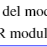



BERcodificador=[];
parfor i=1:m
    %Con codificador
    errors=find(InputCod'~=Xtotal(:,i));
    len_errors=length(errors);
    ber2=len_errors/NumeroBTx;
    BERcodificador=[BERcodificador,ber2]; 
end

load('BERmod.mat')
load pbPSK.mat
%Grafica de la probabilidad de error de bit y BER (Sin codificador de bloque)
curva1=semilogy(snrdB,pbPSK,snrdB,BERmod);
curva1(1).Color='#005DFF';
curva1(1).LineWidth=1.5;
curva1(2).Color='green';
curva1(2).LineWidth=1.5;
title('Probabilidad de error de bit y BER (sin codificador)')
xlabel('$\gamma_ub(dB)$', 'interpreter', 'latex')
ylabel('$P_ub$', 'interpreter', 'latex')
%box on
grid on
legend('$P_ub$ del modulador 4-PSK', ...
    'BER modulador 4-PSK', ...
    'Location', 'best', ...
    'Orientation', 'Vertical', ...
    'Interpreter', 'Latex')

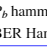


%Grafica de la probabilidad de error de bit y BER (Con codificador de bloque)
curvas2=semilogy(snrdB, pbHam, snrdB,BERcodificador);
curvas2(1).LineWidth=1.5;
curvas2(1).Color='#AB02FF';
curvas2(2).LineWidth=1.5;
curvas2(2).Color='#FF02AB';

title('Probabilidad de error de bit y BER (con codificador)')
xlabel('$\gamma_b(dB)$', 'interpreter', 'latex')
ylabel('$P_b$', 'interpreter', 'latex')
%box on
grid on
legend('$P_b$ hamming(6,3)', ...
    'BER Hamming (6,3)', ...
    'Location', 'best', ...
    'Orientation', 'Vertical', ...
    'Interpreter', 'Latex')

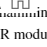

%%Superposición de las curvas
curvas3=semilogy(snrdB,pbPSK,snrdB, pbHam,snrdB,BERmod, snrdB,BERcodificador);
curvas3(1).LineWidth=1.2;
curvas3(1).Color='#005DFF';

curvas3(2).LineWidth=1.2;
curvas3(2).Color='#AB02FF';
curvas3(3).LineWidth=1.2;
curvas3(3).Color='green';
curvas3(4).LineWidth=1.2;
curvas3(4).Color='#FF02AB';


title('Probabilidad de error de bit y BER')
xlabel('$\gamma_b(dB)$', 'interpreter', 'latex')
ylabel('$P_b$', 'interpreter', 'latex')
%box on
grid on
legend('$P_b$ del modulador 4-PSK', ...
    '$P_b$ hamming (6,3)', ...
    'BER modulador 4-PSK', ...
    'BER Hamming (6,3)', ...
    'Location', 'best', ...
    'Orientation', 'Vertical', ...
    'Interpreter', 'Latex')